# Acción de una matriz sobre un vector

# Descomposición SVD (matriz A 2x2)

### 1.- Vector inicial x (rojo)

x=[3;1]

x =      3
     1


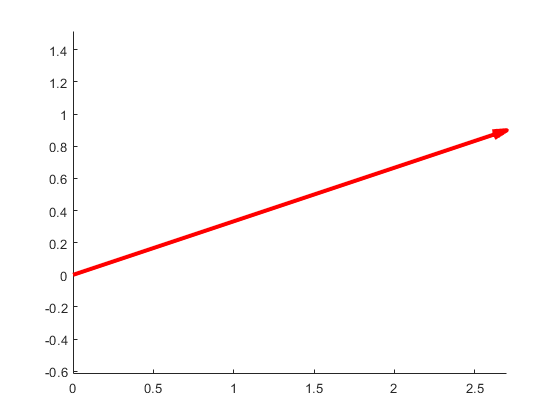

t=0:0.01:2*pi;
%xo=cos(t);yo=sin(t);
% plot(x,y,'.b') % Dibuja círculo unidad
hold on
axis equal
quiver(0,0,x(1),x(2),'r','Linewidth',3,'MaxHeadSize',0.1)

### 2.- Vector transformado y = A.x (magenta)l

A=[1,-2;2,-1]

A =      1    -2
     2    -1


y=A*x

y =      1
     5


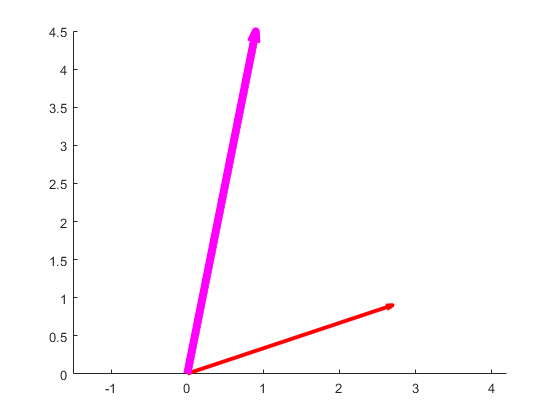

quiver(0,0,y(1),y(2),'m','Linewidth',6,'MaxHeadSize',0.1)

### 3- Descomposición SVD de la matriz

[U S V] = svd(A)

U =    -0.7071   -0.7071
   -0.7071    0.7071


S =     3.0000         0
         0    1.0000


V =    -0.7071    0.7071
    0.7071    0.7071


vtx=V'*x, svtx=S*vtx, usvtx=U*svtx

vtx =    -1.4142
    2.8284


svtx =    -4.2426
    2.8284


usvtx =     1.0000
    5.0000


### 4.- Transformación de x por Vt: vx = Vt .x  (verde)

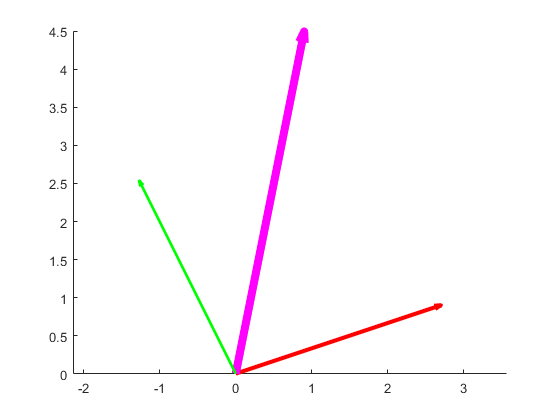

quiver(0,0,vtx(1),vtx(2),'g','Linewidth',2,'MaxHeadSize',0.1) 

rvx=norm(vx);

Undefined function or variable 'vx'.

plot(rvx*cos(t),rvx*sin(t))

### 5.- Transformación de x por S.Vt: svx = S.Vt .x (azul)

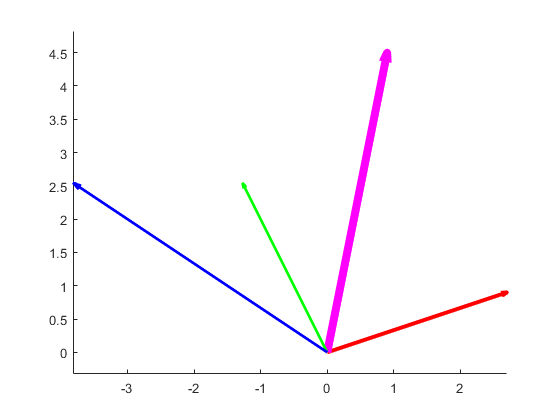

quiver(0,0,svtx(1),svtx(2),'b','Linewidth',2,'MaxHeadSize',0.1)

### 6.- Transformación final de x por U.S.Vt: usvx = U.S.Vt .x (negro)

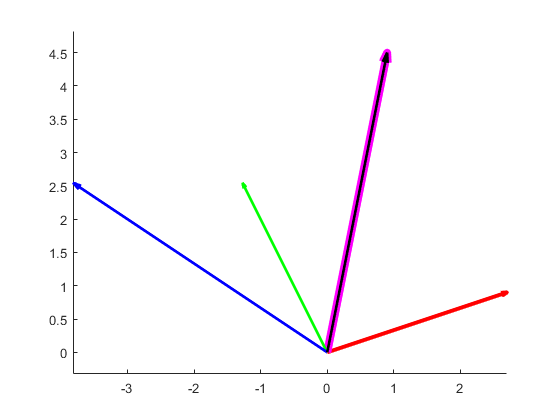

quiver(0,0,usvtx(1),usvtx(2),'k','Linewidth',2,'MaxHeadSize',0.1)

r=norm(usvx);

Undefined function or variable 'usvx'.

plot(r*cos(t),r*sin(t))